Homework #3

ME599 Data Analysis

Aaron Cornelius

2020-10-2

All Matlab code is shown inline next to the figures or calculations generated, for convenience.

warning('off')

### Problem 1

(Note: all calculated responses will be graphed together at the end of the problem.)

Given the following system, ${y^{\prime } }^{\prime } +12y^{\prime } +35y-3=0;y\left(0\right)=0;y^{\prime } \left(0\right)=2$, determine the:

#### a) free response

The free response of the system is the response when the external force term ($-3$) is omitted, and the system is left with no external disturbance:


$${y^{\prime } }^{\prime } +12y^{\prime } +35y=0$$


This can be solved by treating it as a second-order differential equation:


$$\begin{array}{l}
D^2 +12D+35=0\\
=\left(D+5\right)\left(D+7\right)
\end{array}$$


The roots of this are $r_1 =-5,r_2 =-7$. Since both roots are real, the response of the system follows the equation:


$$\begin{array}{l}
y\left(t\right)=c_1 e^{r_1 t} +c_2 e^{r_2 t} \\
=c_1 e^{-5t} +c_2 e^{-7t} 
\end{array}$$


This is differentiated:


$$\begin{array}{l}
\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}=c_1 r_1 e^{r_1 t} +c_2 r_2 e^{r_2 t} \\
=-5c_1 e^{r_1 t} -7c_2 e^{r_2 t} 
\end{array}$$


The initial conditions are now used to solve for the two constants $c_1 ,c_2$:


$$\begin{array}{l}
y\left(0\right)=0;y^{\prime } \left(0\right)=2\\
y\left(0\right)=0=c_1 e^0 +c_2 e^0 =c_1 +c_2 \Rightarrow {-c}_1 =c_2 \\
\frac{\textrm{dy}\left(0\right)}{\textrm{dt}}=2=-5c_1 e^0 -7c_2 e^0 =-5c_1 -7c_2 \\
=-5c_1 +7c_1 =2\Rightarrow c_1 =1\\
\Rightarrow c_2 =-1
\end{array}$$


Therefore, the equation of motion for the free response of the system is:


$$y\left(t\right)=e^{-5t} -e^{-7t}$$


#### b) forced response

The forced response is the response of the equation solely to the forcing equation: i.e., when all the initial conditions are equal to zero. 


$${y^{\prime } }^{\prime } +12y^{\prime } +35y=3$$


The particular solution is determined by setting the differential equation equal to a trial equation of the same form as the forcing function:


$$y\left(t\right)=A$$


This constant value is then solved for:


$$\begin{array}{l}
\frac{\textrm{dy}}{\textrm{dt}}=\frac{\textrm{dA}}{\textrm{dt}}=0\\
\frac{d^2 y}{{\textrm{dt}}^2 }=\frac{d^2 A}{{\textrm{dt}}^2 }=0\\
\Rightarrow 0+12\cdot 0+35A=3\\
\Rightarrow A=\frac{3}{35}
\end{array}$$


This value is then added to an equation of the same form as the free response to give the full particular solution:


$$\begin{array}{l}
{y\left(t\right)}_p =c_1 e^{-5t} +c_2 e^{-7t} +A\\
y^{\prime } {\left(t\right)}_p ={-5c}_1 e^{-5t} -{7c}_2 e^{-7t} \\
{y\left(0\right)}_p =0=c_1 e^0 +c_2 e^0 +\frac{3}{35}\\
\Rightarrow c_1 ={-c}_2 -\frac{3}{35}\\
y^{\prime } {\left(0\right)}_p =0=-5c_1 e^0 -7c_2 e^0 \\
=c_2 =-\frac{5}{7}c_1 \\
\Rightarrow c_1 =\frac{5}{7}c_1 -\frac{3}{35}\\
\Rightarrow \frac{2}{7}c_1 =-\frac{3}{35}\\
\Rightarrow c_1 =-\frac{21}{70}=-\frac{3}{10}\\
\Rightarrow c_2 =-\frac{5}{7}\cdot \left(-\frac{3}{10}\right)=\frac{15}{70}\\
\Rightarrow {y\left(t\right)}_p =-\frac{3}{10}e^{-5t} +\frac{15}{70}e^{-7t} +\frac{3}{35}
\end{array}$$


#### c) total response

The total response is determined by summing the free and forced responses:


$$\begin{array}{l}
y\left(t\right)={y\left(t\right)}_f +{y\left(t\right)}_p =e^{-5t} -e^{-7t} -\frac{3}{10}e^{-5t} +\frac{15}{70}e^{-7t} +\frac{3}{35}\\
\Rightarrow y\left(t\right)=\frac{7}{10}e^{-5t} -\frac{55}{70}e^{-7t} +\frac{3}{35}
\end{array}$$


#### d) steady-state response

The steady-state response is found by taken the limit as $y\left(t\right)$ goes to infinity:


$$\lim_{y\to \infty } y\left(t\right)=\frac{7}{10}e^{-\infty } -\frac{55}{70}e^{-\infty } +\frac{3}{35}=0-0+\frac{3}{35}=\frac{3}{35}$$


This indicates that the response will converge to a single, static value, and not oscillate.

#### e) transient responses

The transient response is found by subtracting the steady-state response from the total response:


$$\frac{7}{10}e^{-5t} -\frac{55}{70}e^{-7t} +\frac{3}{35}-\frac{3}{35}=\frac{7}{10}e^{-5t} -\frac{55}{70}e^{-7t}$$


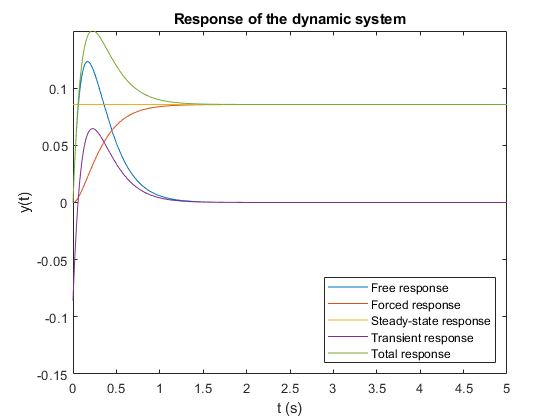

figure
clf
lim = [0 5];
fplot(@(t)exp(-5*t)-exp(-7*t),[0 5])
hold on
fplot(@(t)-3/10*exp(-5*t)+15/70*exp(-7*t)+3/35,[0 5])
fplot(@(t)3/35*ones(size(t)),[0 5])
fplot(@(t)7/10*exp(-5*t)-55/70*exp(-7*t),[0 5])
fplot(@(t)7/10*exp(-5*t)-55/70*exp(-7*t)+3/35,[0 5])

legend(["Free response"...
     "Forced response"...
     "Steady-state response"...
     "Transient response"...
     "Total response"], 'Location', "southeast");
xlabel('t (s)')
ylabel('y(t)')
title('Response of the dynamic system')
ylim([-0.15 0.15])

### Problem 2

Use analytical methods to determine the frequency response function of a physical system with a weighting function $h\left(\tau \right)={\textrm{Ae}}^{-a\tau }$ where $a>0$.

The weighting function $h\left(\tau \right)$ measures the response of the system where 

By definition, the weighting function $h\left(\tau \right)$ is the system response to an input impulse (or Dirac delta function.) The frequency response function is the ratio of the input to the output for every frequency. Therefore, the first step is to transform the input delta function into the frequency domain. The integral of the Dirac delta function across the whole number line is always equal to 1, by definition:


$$\int_{-\infty }^{\infty } \delta \left(x\right)\;\textrm{dx}=1$$


Integrating the convolution of the delta function and another function yields the value of that function at $\tau =0$:


$$\int_{-\infty }^{\infty } \delta \left(x\right)f\left(x\right)\;\textrm{dx}=f\left(0\right)$$


Based on this, the Fourier transform of the delta function can be calculated:


$$\Delta \left(f\right)=\int_{-\infty }^{\infty } \delta \left(\tau \right)\;\exp \left(-j\;2\pi \;f\tau \right)\;d\tau =\exp \left(0\right)=1$$


This confirms a known fact, that the Fourier transform of the impulse functions is a constant value of 1. Therefore, the frequency response function will simply be $\frac{H\left(f\right)}{1}=H\left(f\right)$.

Now the Fourier transform of $h\left(\tau \right)$ is calculated:


$$\begin{array}{l}
H\left(f\right)=\int_0^{\infty } h\left(\tau \right)\exp \left(-j\;2\pi \;f\;\tau \right)\;d\tau =A\int_0^{\infty } \exp \left(-a\tau \right)\;\exp \left(-j\;2\pi \;\omega \;\tau \right)\;d\tau \\
=A\int_0^{\infty } \exp \left(-\tau \left(a+j\;2\pi \;f\right)\right)\;d\tau \\
=A\cdot \frac{-1}{a+j\;2\pi \;f}\;\exp \left(-\tau \left(a+j\;2\pi \;f\right)\right){\left|\right.}_0^{\infty } \\
=\frac{-A}{a+j\;2\pi \;f}\;\left(\exp \left(-\tau \;a\right)\cdot \exp \left(-\tau \;j\;2\pi \;f\right)\right){\left|\right.}_0^{\infty } \\
=\frac{-A}{a+j\;2\pi \;f}\;\left(\exp \left(-\tau \;a\right)\cdot \left(\cos \left(-\tau \;2\pi \;f\right)+j\;\sin \left(-\tau \;2\pi \;f\right)\right)\right){\left|\right.}_0^{\infty } \\
=\frac{-A}{a+j\;2\pi \;f}\;\left(\exp \left(-\tau \;a\right)\cdot \left(\cos \left(\tau \;2\pi \;f\right)-j\;\sin \left(\tau \;2\pi \;f\right)\right)\right){\left|\right.}_0^{\infty } \\
=\frac{-A}{a+j\;2\pi \;f}\;\left(\exp \left(-\infty \right)\cdot \left(\cos \left(\infty \right)-j\;\sin \left(\infty \right)\right)-\exp \left(0\right)\cdot \left(\cos \left(0\right)-j\;\sin \left(0\right)\right)\right)\\
=\frac{-A}{a+j\;2\pi \;f}\;\left(0\cdot \left(\cos \left(\infty \right)-j\;\sin \left(\infty \right)\right)-1\cdot \left(1-0j\right)\right)\\
=\frac{A}{a+j\;2\pi \;f}\;\\
=\frac{a-j\;2\pi f}{a-j\;2\pi f}\cdot \frac{A}{a+j\;2\pi \;f}=\frac{A\left(a-j\;2\pi \;f\right)}{a^2 +4\pi^2 f^2 }
\end{array}$$


This can be seperated in the the real and imaginary components:


$${H\left(f\right)}_{\textrm{real}} =\frac{\textrm{Aa}}{a^2 +4\pi^2 f^2 },{H\left(f\right)}_{\textrm{imag}} =\frac{-2\pi \;\textrm{Af}}{a^2 +4\pi^2 f^2 }$$


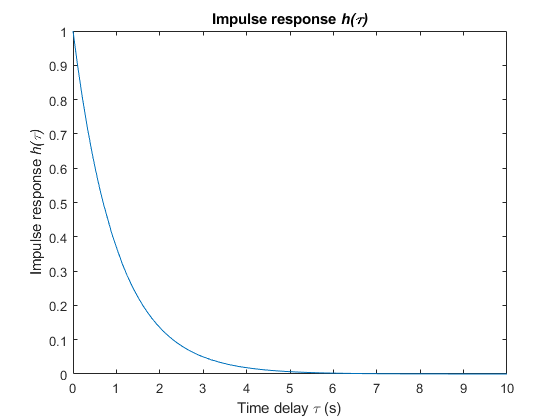

figure
A = 1;
a = 1;
h = @(tau) A .* exp(-a .* tau);

fplot(h, [0 10])
title('Impulse response \it{h(\tau)}')
xlabel('Time delay \tau (s)')
ylabel('Impulse response \it{h(\tau)}')

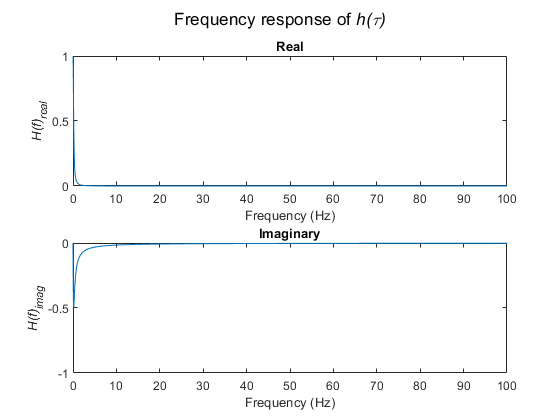


Hreal = @(f) A.*a./(a.^2+4.*pi.^2.*f.^2);
Himag = @(f) -2.*pi.*A.*f./(a.^2+4.*pi.^2.*f.^2);

figure
subplot(2,1,1)
fplot(Hreal, [0 100])
xlabel('Frequency (Hz)')
ylabel('\it{H(f)_{real}}')
title('Real')
subplot(2,1,2)
fplot(Himag, [0 100])
title('Imaginary')
xlabel('Frequency (Hz)')
ylabel('\it{H(f)_{imag}}')
title('Imaginary')
sgtitle('Frequency response of \it{h(\tau)}')
ylim([-1, 0])

### Problem 3

Plot the impulse response function $h\left(t\right)$ against the quantity $\omega_n t$ for each of the pole positions shown below in the complex plane. Make one graph for each colored line (total of three graphs) and identify that graph as having a constant damping ratio, time constant, or oscillation frequency, etc. Note that these need their own compex conjugate pairs (omitted from this figure for simplicity)

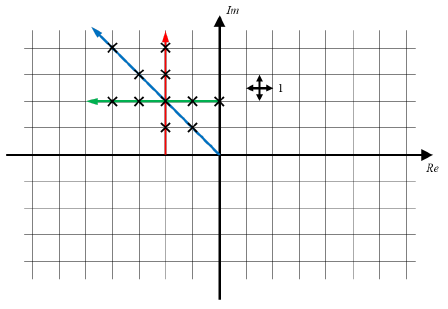

The solutions are all of the form $h\left(t\right)=\exp \left(t\left(-\zeta \omega_n \pm j\omega_n \sqrt{1-\zeta^2 }\right)\right)$. The real portion corresponds to the $-\zeta \omega_n$ portion of the exponential, while the imaginary portion is $\omega_n \sqrt{1-\zeta^2 }$. For all examples, the complex conjugate solution's real component is equal to the original, but the imaginary component is swapped in sign. For clarity, the complex conjugates will be omitted from the real section of each graph, to reduce clutter.

% Define the impulse response formulas
realImpulseResponse =@(re, im) (@(t) real(exp(t.*(re + 1i.*im))));
imagImpulseResponse =@(re, im) (@(t) imag(exp(t.*(re + 1i.*im))));

The red line represents constant time constant.

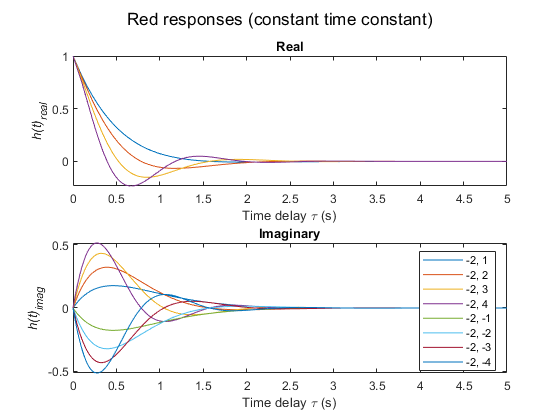

% Red line. Constant time constant
figure
clf
lim = [0 5];
subplot(2,1,1)
fplot(realImpulseResponse(-2,1), lim)
hold on
fplot(realImpulseResponse(-2,2), lim)
fplot(realImpulseResponse(-2,3), lim)
fplot(realImpulseResponse(-2,4), lim)
title('Real')
sgtitle('Red responses (constant time constant)')
xlabel('Time delay \tau (s)')
ylabel('\it{h(t)_{real}}')

subplot(2,1,2)
fplot(imagImpulseResponse(-2,1), lim)
hold on
fplot(imagImpulseResponse(-2,2), lim)
fplot(imagImpulseResponse(-2,3), lim)
fplot(imagImpulseResponse(-2,4), lim)
fplot(imagImpulseResponse(-2,-1), lim)
fplot(imagImpulseResponse(-2,-2), lim)
fplot(imagImpulseResponse(-2,-3), lim)
fplot(imagImpulseResponse(-2,-4), lim)
legend(["-2, 1" ...
    "-2, 2" ...
    "-2, 3", ...
    "-2, 4" ...
    "-2, -1" ...
    "-2, -2" ...
    "-2, -3" ...
    "-2, -4"])
title('Imaginary')
xlabel('Time delay \tau (s)')
ylabel('\it{h(t)_{imag}}')

The green line represents constant damped natural frequency $\omega_d$:

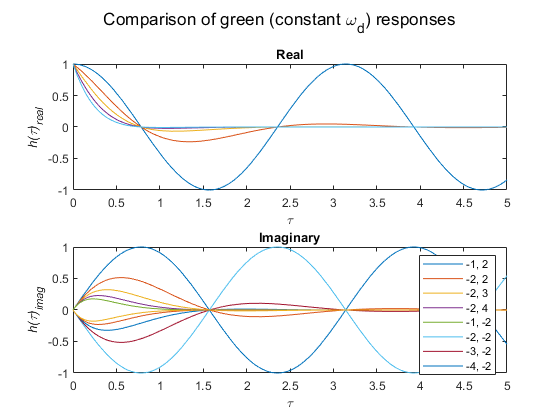

% Green line. Constant omega_d
figure
clf
lim = [0 5];
subplot(2,1,1)
fplot(realImpulseResponse(0,2), lim)
sgtitle('Comparison of green (constant \omega_d) responses')
hold on
fplot(realImpulseResponse(-1,2), lim)
fplot(realImpulseResponse(-2,2), lim)
fplot(realImpulseResponse(-3,2), lim)
fplot(realImpulseResponse(-4,2), lim)

fplot(realImpulseResponse(-4,-2), lim)
title('Real')
xlabel('\tau')
ylabel('\it{h(\tau)}_{real}')
subplot(2,1,2)
fplot(imagImpulseResponse(0,2), lim)
hold on
fplot(imagImpulseResponse(-1,2), lim)
fplot(imagImpulseResponse(-2,2), lim)
fplot(imagImpulseResponse(-3,2), lim)
fplot(imagImpulseResponse(-4,2), lim)
fplot(imagImpulseResponse(0,-2), lim)
fplot(imagImpulseResponse(-1,-2), lim)
fplot(imagImpulseResponse(-2,-2), lim)
fplot(imagImpulseResponse(-3,-2), lim)
fplot(imagImpulseResponse(-4,-2), lim)

title('Imaginary')
xlabel('\tau')
ylabel('\it{h(\tau)}_{imag}')
legend(["-1, 2" ...

    "-2, 2" ...
    "-2, 3" ...
    "-2, 4" ...
    "-1, -2" ...
    "-2, -2" ...
    "-3, -2" ...
    "-4, -2"])

The blue responses have constant natural frequency. This does not mean that they will all oscillate at the same frequency, however, since they have different damped frequencies.

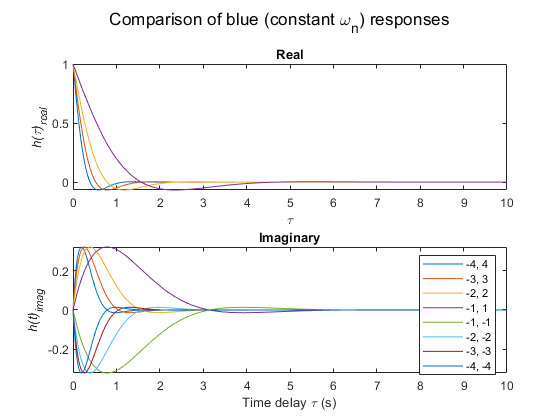

% Blue line. Constant omega_n
figure
clf

lim = [0 10];
subplot(2,1,1)
fplot(realImpulseResponse(-4,4), lim)
hold on
fplot(realImpulseResponse(-3,3), lim)
fplot(realImpulseResponse(-2,2), lim)
fplot(realImpulseResponse(-1,1), lim)
sgtitle('Comparison of blue (constant \omega_n) responses')
title('Real')
xlabel('\tau')
ylabel('\it{h(\tau)}_{real}')
subplot(2,1,2)

fplot(imagImpulseResponse(-4,4), lim)
hold on
fplot(imagImpulseResponse(-3,3), lim)
fplot(imagImpulseResponse(-2,2), lim)
fplot(imagImpulseResponse(-1,1), lim)
fplot(imagImpulseResponse(-1,-1), lim)
fplot(imagImpulseResponse(-2,-2), lim)
fplot(imagImpulseResponse(-3,-3), lim)
fplot(imagImpulseResponse(-4,-4), lim)
legend(["-4, 4" ...
    "-3, 3", ...
    "-2, 2", ...
    "-1, 1" ...
    "-1, -1" ...
    "-2, -2" ...
    "-3, -3" ...
    "-4, -4"])
title('Imaginary')
title('Imaginary')
xlabel('Time delay \tau (s)')
ylabel('\it{h(t)_{imag}}')

### Problem 4

A first-order system with an impulse response function of $h\left(t\right)=\frac{1}{a}\exp \left(-\frac{t}{a}\right)$ is excited by a single square wave pulse $x\left(t\right)$:

If the time constant is $a=2\;\left\lbrack \mathrm{s}\right\rbrack$,

#### a) Analytically determine the system output y(t)

Determine the system output y(t) by applying the convolution integral analytically. HINT: be careful to use the proper integration limits for the different delays.

We are looking for the forced response to this input. The forced response can be described in terms of the convolution integral:


$$\begin{array}{l}
y\left(t\right)=\int_{-\infty }^{\infty } h\left(\tau \right)u\left(t-\tau \right)\;d\tau \\
y\left(t\right)=\int_0^{4a} h\left(\tau \right)u\left(t-\tau \right)\;d\tau \\
y\left(t\right)=\int_0^{2a} h\left(\tau \right)\cdot \left(-1\right)\;d\tau +\int_{2a}^{4a} h\left(\tau \right)\cdot \left(1\right)\;d\tau \\
y\left(t\right)=\int_{2a}^{4a} \frac{1}{a}\exp \left(-\frac{\tau }{a}\right)\;d\tau -\int_0^{2a} \frac{1}{a}\exp \left(-\frac{\tau }{a}\right)\;d\tau \\
y\left(t\right)=\frac{1}{a}\left(\int_{2a}^{4a} \exp \left(-\frac{\tau }{a}\right)\;d\tau -\int_0^{2a} \exp \left(-\frac{\tau }{a}\right)\;d\tau \right)
\end{array}$$



$$y\left(t\right)=\int_{-\infty }^{\infty } h\left(\tau \right)u\left(t-\tau \right)\;d\tau$$


This must be evaluated piecewise, since it is assumed that $h\left(\tau \right)=0$ for $\tau <0$: the system cannot "look forward" and respond to inputs before they occur. Therefore, this function must be broken up into four sections, depending on which case of the input function $x\left(t\right)$ is "active" at the current time.

First, look at the case where $t<0$. Here, there is only one case for $x\left(t\right)$ looking "backwards" in time: it always equals 0:


$${y\left(t\right)}_{t<0} =\int_0^{\infty } h\left(\tau \right)u\left(t-\tau \right)\;d\tau =\int_0^{\infty } h\left(\tau \right)\cdot 0\;d\tau =0$$


Next, examine the case where $0\le t<2a$. Technically, there are two cases for $x\left(t\right)$, but since it has been demonstrated that ${y\left(t\right)}_{t<0} =0$, this can be omitted. The integration bounds are set based on the current time being analyzed:


$${y\left(t\right)}_{0\le t<2a} =\int_0^t h\left(\tau \right)\cdot u\left(t-\tau \right)\;d\tau =\int_0^t \frac{1}{a}\exp \left(-\frac{\tau }{a}\right)\cdot 1\;d\tau =\int_0^t \frac{1}{a}\exp \left(-\frac{\tau }{a}\right)\;d\tau$$


The integral of an exponential is known to be $\int e^{\textrm{ax}} =\frac{1}{a}e^{\textrm{ax}}$. Therefore, this integral can be evaluated as:


$${y\left(t\right)}_{0\le t<2a} =\left(-\frac{a}{a}\exp \left(-\frac{\tau }{a}\right)\right){\left|\right.}_0^t =-\left(\exp \left(-\frac{t}{a}\right)-\exp \left(0\right)\right)=1-\exp \left(-\frac{t}{a}\right)$$


Next, the time period where $2a\le t<4a$ is examined. Here, there are two functional (non-trivial) cases for $x\left(t\right)$, which must be evaluated seperately. This can be expressed as:


$$\begin{array}{l}
{y\left(t\right)}_{2a\le t<4a} =\int_0^{t-2a} h\left(\tau \right)\cdot u\left(t-\tau \right)\;d\tau +\int_{t-2a}^t h\left(\tau \right)\cdot u\left(t-\tau \right)\;d\tau =\int_0^{t-2a} h\left(\tau \right)\cdot \left(-1\right)\;d\tau +\int_{t-2a}^t h\left(\tau \right)\cdot 1\;d\tau \\
{y\left(t\right)}_{2a\le t<4a} =\int_{t-2a}^t \frac{1}{a}\exp \left(-\frac{\tau }{a}\right)\;d\tau -\int_0^{t-2a} \frac{1}{a}\exp \left(-\frac{\tau }{a}\right)\;d\tau =\frac{1}{a}\cdot \left(\int_{t-2a}^t \exp \left(-\frac{\tau }{a}\right)\;d\tau -\int_0^{t-2a} \exp \left(-\frac{\tau }{a}\right)\;d\tau \right)
\end{array}$$


As before, this can be evaluated based on the integral of an exponential function $\int e^{\textrm{ax}} =\frac{1}{a}e^{\textrm{ax}}$:


$$\begin{array}{l}
{y\left(t\right)}_{2a\le t<4a} =\frac{1}{a}\cdot \left(\left(-a\cdot \exp \left(-\frac{\tau }{a}\right)\right){\left|\right.}_{t-2a}^t -\left(-a\cdot \exp \left(-\frac{\tau }{a}\right)\right){\left|\right.}_0^{t-2a} \right)=\left(\left(\exp \left(-\frac{\tau }{a}\right)\right){\left|\right.}_0^{t-2a} -\left(\exp \left(-\frac{\tau }{a}\right)\right){\left|\right.}_{t-2a}^t \right)\\
{y\left(t\right)}_{2a\le t<4a} =\left(\exp \left(-\frac{t-2a}{a}\right)-\exp \left(0\right)-\exp \left(-\frac{t}{a}\right)+\exp \left(-\frac{t-2a}{a}\right)\right)\\
{y\left(t\right)}_{2a\le t<4a} =2\cdot \exp \left(-\frac{t-2a}{a}\right)-1-\exp \left(-\frac{t}{a}\right)
\end{array}$$


Now, the last case where $4a\le t$ is examined. Since ${x\left(t\right)}_{t\ge 4a} =0$, there are still only two non-trivial cases for $x\left(t\right)$:


$$\begin{array}{l}
{y\left(t\right)}_{t\ge 4a} =\int_{t-4a}^{t-2a} h\left(\tau \right)\cdot u\left(t-\tau \right)\;d\tau +\int_{t-2a}^t h\left(\tau \right)\cdot u\left(t-\tau \right)\;d\tau =\int_{t-4a}^{t-2a} h\left(\tau \right)\cdot \left(-1\right)\;d\tau +\int_{t-2a}^t h\left(\tau \right)\cdot 1\;d\tau \\
{y\left(t\right)}_{t\ge 4a} =\int_{t-2a}^t \frac{1}{a}\exp \left(-\frac{\tau }{a}\right)\;d\tau -\int_{t-4a}^{t-2a} \frac{1}{a}\exp \left(-\frac{\tau }{a}\right)\;d\tau =\frac{1}{a}\cdot \left(\int_{t-2a}^t \exp \left(-\frac{\tau }{a}\right)\;d\tau -\int_{t-4a}^{t-2a} \exp \left(-\frac{\tau }{a}\right)\;d\tau \right)\\
{y\left(t\right)}_{t\ge 4a} =\frac{1}{a}\cdot \left(\left(-a\cdot \exp \left(-\frac{\tau }{a}\right)\right){\left|\right.}_{t-2a}^t -\left(-a\cdot \exp \left(-\frac{\tau }{a}\right)\right){\left|\right.}_{t-4a}^{t-2a} \right)=\left(\left(\exp \left(-\frac{\tau }{a}\right)\right){\left|\right.}_{t-4a}^{t-2a} -\left(\exp \left(-\frac{\tau }{a}\right)\right){\left|\right.}_{t-2a}^t \right)\\
{y\left(t\right)}_{t\ge 4a} =\left(\left(\exp \left(-\frac{t-2a}{a}\right)-\exp \left(-\frac{t-4a}{a}\right)\right)-\left(\exp \left(-\frac{t}{a}\right)-\exp \left(-\frac{t-2a}{a}\right)\right)\right)\\
{y\left(t\right)}_{t\ge 4a} =2\cdot \exp \left(-\frac{t-2a}{a}\right)-\exp \left(-\frac{t-4a}{a}\right)-\exp \left(-\frac{t}{a}\right)
\end{array}$$


#### b) Discretize the system output y(t) through numerical convolution methods

The system can be discretized by defining the $h\left(\tau \right)$ and $x\left(t\right)$ functions and then integrating numerically:

a=2;
hFunc = @(t) 1/a .* exp(-t/a);
xFunc = @(t) (t<=2.*a & t>0) + -1.*(t<=4.*a & t> 2.*a);
yFunc = @(t) integral(@(tau) hFunc(tau).*xFunc(t-tau), 0, t);

#### c) Graph the forcing function and the analytical solutions

First, the forcing function will be graphed. The Matlab function for this was defined in part b of this equation.

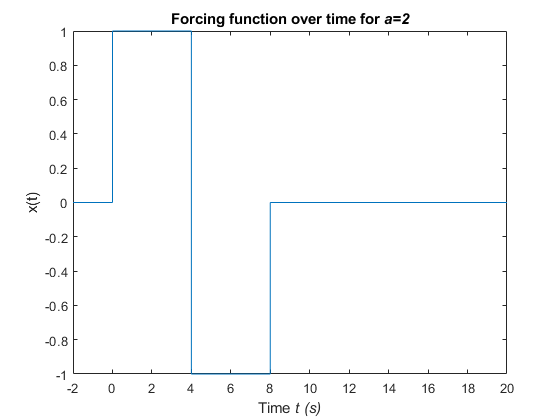

figure
clf
fplot(xFunc,[-2 20])
xlabel('Time \it{t} (s)')
ylabel('x(t)')
title('Forcing function over time for \it{a=2}')

Now the numerical and analytical responses are graphed. The numerical response will be solid, while the piece-wise analytical response is overlaid on top in dashed lines:

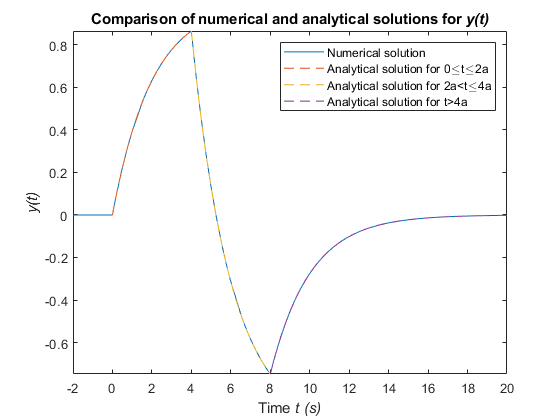

figure
clf
fplot(yFunc, [-2, 20])
hold on
fplot(@(x)1-exp(-x/a), [0 2*a], '--')
fplot(@(x)(2*exp(-(x-2*a)/a)-1-exp(-x/a)), [2*a, 4*a], '--')
fplot(@(x)(2*exp(-(x-2*a)/a)-exp(-(x-4*a)/a)-exp(-x/a)),[4*a, 10*a], '--');
legend(["Numerical solution", ...
    "Analytical solution for 0{\leq}t{\leq}2a", ...
    "Analytical solution for 2a<t\leq4a" ...
    "Analytical solution for t>4a"])
title('Comparison of numerical and analytical solutions for \it{y(t)}')
xlabel('Time \it{t} (s)')
ylabel('\it{y(t)}')

#### d) Interpret your results. Does everything make physical sense? Explain.

This represents the response of a single-order system to abrupt step inputs at times $t=2a,4a$. The system starts at rest. When an input is applied, the response begins to converge to that input. An example of this might be a thermometer with non-zero thermal mass which is abruptly moved between different temperature regions and begins acclimating to each one before being moved again. Of course, a real system cannot have infinitely fast changes in input, but it could be a reasonable approximation if, for example, the thermal mass of the thermometer was sufficiently high compared to the difference in temperature between the regions.

### Problem 5

A second order system with an impulse response function of $h\left(t\right)=\frac{\omega_n }{\sqrt{1-\zeta^2 }}e^{-\zeta \omega_n t} \sin \left(\omega_d t\right)$ is excited by the truncated step fuction input $x\left(t\right):$


$$x\left(t\right)=\left\lbrace \begin{array}{ll}
2 & 0\le t\le 2T\\
0 & \textrm{otherwise}
\end{array}\right.$$


Given $\omega_n =1\;\left\lbrack \frac{\textrm{rad}}{\mathrm{s}}\right\rbrack ,\zeta =0\ldotp 2,\omega_d =\omega_n \sqrt{1-\zeta^2 },T=\frac{2\pi }{\omega_d }\left\lbrack \mathrm{s}\right\rbrack$:

#### a) Analytically determine the system output $y\left(t\right)$

The function can be split into three piecewise sections. First, there is the time period where $t<0$. As shown in problem (4), since ${x\left(t\right)}_{t<0}$ is always 0, ${y\left(t\right)}_{t<0} =0$. This section is thus trivial and can be ommitted.

Second, there is the time period where $0\le t\le 2T$. This section can be computed using the convolution integral (the limits are set from the fact that ${h\left(\tau \right)}_{\tau <0} =0$ and ${x\left(t\right)}_{t<0} =0$:


$${y\left(t\right)}_{0\le t\le 2T} =\int_0^t h\left(\tau \right)u\left(t-\tau \right)\;d\tau =\int_0^t \frac{\omega_n }{\sqrt{1-\zeta^2 }}e^{-\zeta \omega_n \tau } \sin \left(\omega_d \tau \right)\cdot 2\;d\tau =\frac{2\cdot \omega_n }{\sqrt{1-\zeta^2 }}\int_0^t e^{-\zeta \omega_n \tau } \sin \left(\omega_d \tau \right)\;d\tau$$


This integral is of the form $\int \exp \left(a\;x\right)\sin \left(b\;x\right)\;\textrm{dx}$. It can be solved by combining that integral with $\int \exp \left(a\;x\right)\;\cos \left(b\;x\right)\;\textrm{dx}$ and using Euler's formula to convert the entire formula into a single exponential:


$$\begin{array}{l}
\int i\;\exp \left(a\;x\right)\;\sin \left(b\;x\right)\;\textrm{dx}+\int \exp \left(a\;x\right)\;\cos \left(b\;x\right)\;\textrm{dx}=\int \exp \left(a\;x\right)\cdot \left(\cos \left(b\;x\right)+i\;\sin \left(b\;x\right)\right)\\
=\int \exp \left(x\;\left(a+i\;b\right)\right)\;\textrm{dx}
\end{array}$$


This is a straightforward exponential integration:


$$\begin{array}{l}
\int \exp \left(x\;\left(a+i\;b\right)\right)\;\textrm{dx}=\frac{1}{a+i\;b}\exp \left(x\left(a+i\;b\right)\right)\\
=\frac{a-i\;b}{a-i\;b}\cdot \frac{1}{a+i\;b}\exp \left(x\left(a+i\;b\right)\right)\\
=\frac{a-i\;b}{a^2 +b^2 }\cdot \exp \left(x\left(a+i\;b\right)\right)
\end{array}$$


Now Euler's formula is used again to separate the trigonometric functions:


$$\begin{array}{l}
\int \exp \left(x\;\left(a+i\;b\right)\right)\;\textrm{dx}=\frac{a-i\;b}{a^2 +b^2 }\cdot \exp \left(a\;x\right)\left(\cos \left(b\;x\right)+i\;\sin \left(b\;x\right)\right)\\
=\frac{1}{a^2 +b^2 }\cdot \exp \left(a\;x\right)\left(a\;\cos \left(b\;x\right)-i\;b\;\cos \left(b\;x\right)+a\;i\;\sin \left(b\;x\right)+b\;\sin \left(b\;x\right)\right)
\end{array}$$


The imaginary component is the integral of the imaginary component of the original integral:


$$\begin{array}{l}
\int i\;\exp \left(a\;x\right)\;\sin \left(b\;x\right)\;\textrm{dx}=\frac{1}{a^2 +b^2 }\cdot \exp \left(a\;x\right)\left(a\;i\;\sin \left(b\;x\right)-i\;b\;\cos \left(b\;x\right)\right)\\
\Rightarrow \int \exp \left(a\;x\right)\;\sin \left(b\;x\right)\;\textrm{dx}=\frac{\exp \left(a\;x\right)}{a^2 +b^2 }\cdot \left(a\;\sin \left(b\;x\right)-b\;\cos \left(b\;x\right)\right)
\end{array}$$


Recall that ${y\left(t\right)}_{0\le t\le 2T} =\frac{2\cdot \omega_n }{\sqrt{1-\zeta^2 }}\int_0^t e^{-\zeta \omega_n \tau } \sin \left(\omega_d \tau \right)\;d\tau$. This can be integrated as ${y\left(t\right)}_{0\le t\le 2T} =\int \exp \left(a\;x\right)\sin \left(b\;x\right)\;\textrm{dx}$ where$a=-\zeta \omega_n ,b=\omega_d$. Therefore:


$$\begin{array}{l}
{y\left(t\right)}_{0\le t\le 2T} =\frac{2\cdot \omega_n }{\sqrt{1-\zeta^2 }}\cdot \left(\frac{\exp \left(-\zeta \omega_n \;\tau \right)}{{\left(-\zeta \omega_n \right)}^2 +{\omega_d }^2 }\cdot \left(-\zeta \omega_n \;\sin \left(\omega_d \;\tau \right)-\omega_d \;\cos \left(\omega_d \;\tau \right)\right)\right){\left|\right.}_0^t \\
=\frac{-2\cdot \omega_n }{\left(\zeta^2 \omega_n^2 +\omega_d^2 \right)\sqrt{1-\zeta^2 }}\cdot \left(\exp \left(-\zeta \omega_n \;\tau \right)\cdot \left(\zeta \omega_n \;\sin \left(\omega_d \;\tau \right)+\omega_d \;\cos \left(\omega_d \;\tau \right)\right)\right){\left|\right.}_0^t \\
=\frac{-2\cdot \omega_n }{\left(\zeta^2 \omega_n^2 +\omega_d^2 \right)\sqrt{1-\zeta^2 }}\cdot \left(\left(\exp \left(-\zeta \omega_n \;t\right)\cdot \left(\zeta \omega_n \;\sin \left(\omega_d \;t\right)+\omega_d \;\cos \left(\omega_d \;t\right)\right)\right)-\left(\exp \left(0\right)\cdot \left(\zeta \omega_n \;\sin \left(0\right)+\omega_d \;\cos \left(0\right)\right)\right)\right)\\
=\frac{-2\cdot \omega_n }{\left(\zeta^2 \omega_n^2 +\omega_d^2 \right)\sqrt{1-\zeta^2 }}\cdot \left(\left(\exp \left(-\zeta \omega_n \;t\right)\cdot \left(\zeta \omega_n \;\sin \left(\omega_d \;t\right)+\omega_d \;\cos \left(\omega_d \;t\right)\right)\right)-\left(\omega_d \right)\right)
\end{array}$$


Using the same techniques:


$$\begin{array}{l}
{y\left(t\right)}_{t>2T} =\frac{2\cdot \omega_n }{\sqrt{1-\zeta^2 }}\cdot \left(\frac{\mathrm{exp}\left(-\zeta \omega_n \;\tau \right)}{{\left(-\zeta \omega_n \right)}^2 +{\omega_d }^2 }\cdot \left(-\zeta \omega_n \;\mathrm{sin}\left(\omega_d \;\tau \right)-\omega_d \;\mathrm{cos}\left(\omega_d \;\tau \right)\right)\right){\left|\right.}_{t-2T}^t y\\
=\frac{-2\cdot \omega_n }{\left(\zeta^2 \omega_n^2 +\omega_d^2 \right)\sqrt{1-\zeta^2 }}\cdot \\
\;\;\;\;\left(\left(\mathrm{exp}\left(-\zeta \omega_n \;t\right)\cdot \left(\zeta \omega_n \;\mathrm{sin}\left(\omega_d \;t\right)+\omega_d \;\mathrm{cos}\left(\omega_d \;t\right)\right)\right)-\left(\mathrm{exp}\left(-\zeta \omega_n \left(t-2T\right)\right)\cdot \left(\zeta \omega_n \;\mathrm{sin}\left(\omega_d \left(t-2T\right)\right)+\omega_d \;\mathrm{cos}\left(\omega_d \left(t-2T\right)\right)\right)\right)\right)
\end{array}$$


#### b) Find the system output $y\left(t\right)$ numerically

The numerical integration of the system can be defined using the following functions:

omega_n=1;
zeta = 0.2;
omega_d = omega_n*sqrt(1-zeta.^2);
T = 2*pi/omega_d;
hFunc = @(t) omega_n./(1-zeta.^2).^0.5.*exp(-zeta*omega_n*t).*sin(omega_d.*t);
xFunc = @(t) 2*(t<=2.*T & t>=0);
yFunc = @(t) integral(@(tau) hFunc(tau).*xFunc(t-tau), 0, t);


#### c) Graph the forcing function and the analytical/numerical responses

First, the forcing function is graphed:

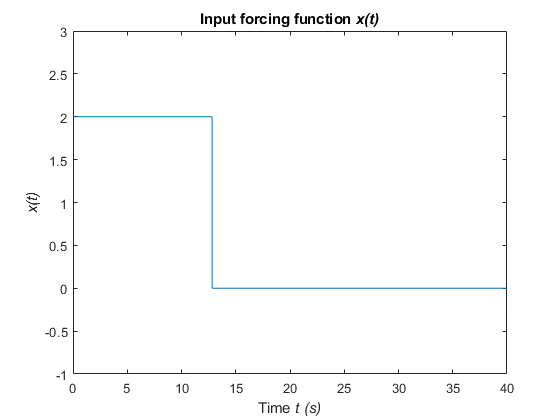

figure
clf
fplot(xFunc, [0, 40])
xlabel('Time \it{t} (s)')
ylabel('\it{x(t)}')
title('Input forcing function \it{x(t)}')
ylim([-1 3])

Now the responses are plotted. The numerical response is plotted in solid, and the piecewise analytical responses are plotted on top of it using dashed lines.

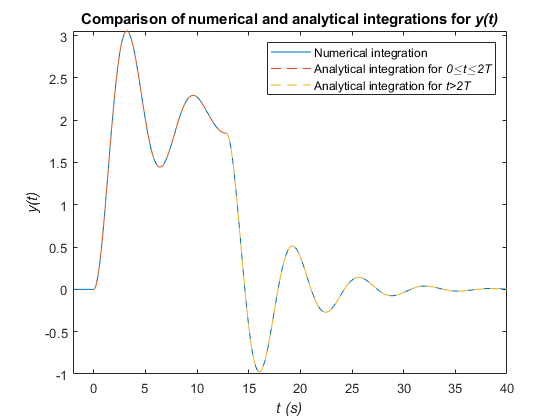

yanal1 = @(t)-2*omega_n/((zeta.^2*omega_n.^2 + omega_d.^2)*sqrt(1-zeta.^2))* ...
    (exp(-zeta*omega_n*t)*(zeta*omega_n*sin(omega_d*t)+omega_d*cos(omega_d*t))-omega_d);
yanal2 = @(t)-2*omega_n/((zeta.^2*omega_n.^2 + omega_d.^2)*sqrt(1-zeta.^2))* ...
    (exp(-zeta*omega_n*t)*(zeta*omega_n*sin(omega_d*t)+omega_d*cos(omega_d*t))- ...
    (exp(-zeta*omega_n*(t-2*T)))*(zeta*omega_n*sin(omega_d*(t-2*T))+ ...
    omega_d*cos(omega_d*(t-2*T))));

figure
clf
fplot(yFunc, [-2, 40])
hold on
fplot(yanal1, [0, 2*T], '--')
fplot(yanal2, [2*T, 40], '--')
legend(["Numerical integration" ...
    "Analytical integration for \it{0{\leq}t{\leq}2T}" ...
    "Analytical integration for \it{t>2T}"])
xlabel('\it{t} (s)')
ylabel('\it{y(t)}')
title('Comparison of numerical and analytical integrations for \it{y(t)}')

#### d) Interpret your resuts. Does everything make physical sense? Explain.

This response function models an underdamped system which will oscillate towards and converge to a given input value, given sufficient time. One possible system that would model this response is a sliding base with a floating mass attached via spring mass damper system. Before $t=0$, the system is at rest, with the spring at equilibrium. At $t=0$, the slider is very quickly slid up some distance. The inertia of the mass causes it to lag behind. Over time, the spring will pull the block up towards the base. However, it will overshoot since the system is underdamped, and will oscillate around the new equilibrium value while losing energy through the viscous damper. However, at $t=2T$, the base is displaced back to the original starting position. The mass then begins oscillating towards its original position, and over time will converge towards the same position it had when it was originally at rest.

Of course in reality the system can't be displaced infinitely quickly. However, this could be an acceptable model if the displacement is extremely fast relative to the system response: for example, if the spring force is very low relative to the mass.

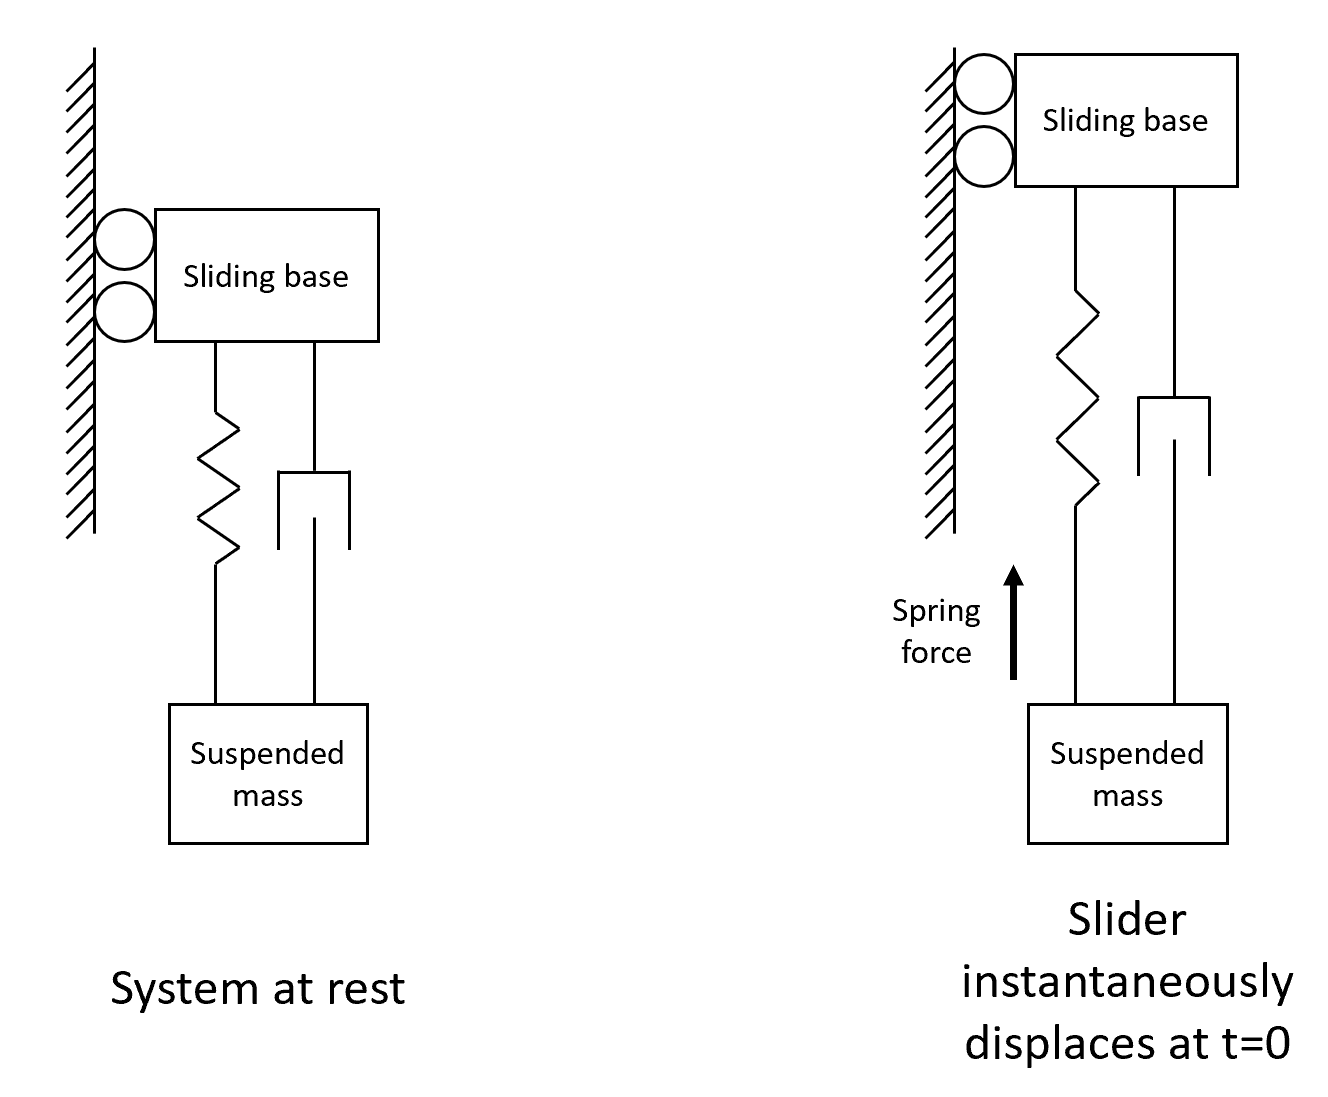

### Problem 6

Given the convolution integral $y\left(t\right)=\int_{-\infty }^{\infty } u\left(\tau \right)h\left(t-\tau \right)\;d\tau$ and the definition of the Fourier transform $Y\left(\omega \right)=\int_{-\infty }^{\infty } y\left(t\right)e^{-j\omega t} \;\textrm{dt}$, prove that $Y\left(\omega \right)=U\left(\omega \right)H\left(\omega \right)$.

First, take the Fourier transform of the product of $u\left(t\right),h\left(t\right)$:


$$U\left(\omega \right)H\left(\omega \right)=\int_{-\infty }^{\infty } u\left(t\right)h\left(t\right)\;e^{-j\omega t} \;\textrm{dt}$$


Using the inverse Fourier transform $\int_{-\infty }^{\infty } f\left(x\right)\;e^{j\omega x} \;\textrm{dx}$, this can be rewritten as:


$$\int_{-\infty }^{\infty } \left(\int_{-\infty }^{\infty } U\left(\tau \right)e^{j\omega \tau } \;d\tau \right)h\left(t\right)\;e^{-j\omega t} \;\textrm{dt}$$


Since it is not a function of $\tau$, the $h\left(t\right)\;e^{-j\omega t}$ term can be brought inside the second integral:


$$\int_{-\infty }^{\infty } \left(\int_{-\infty }^{\infty } U\left(\tau \right)e^{j\omega \tau } \;h\left(t\right)\;e^{-j\omega t} \;d\tau \right)\textrm{dt}=\int_{-\infty }^{\infty } \left(\int_{-\infty }^{\infty } U\left(\tau \right)e^{-j\omega \left(t-\tau \right)} \;h\left(t\right)\;d\tau \right)\textrm{dt}$$


The integrals can now be swapped, allowing for the $U\left(\tau \right)$ term to be brought to the outer integral:


$$\int_{-\infty }^{\infty } \left(\int_{-\infty }^{\infty } {h\left(t\right)e}^{-j\omega \left(t-\tau \right)} \;\;\textrm{dt}\right)U\left(\tau \right)\;d\tau =\int_{-\infty }^{\infty } H\left(t-\tau \right)\;U\left(\tau \right)\;d\tau$$


Since $H\left(t-\tau \right)\;U\left(\tau \right)=F\left(h\left(t-\tau \right)u\left(\tau \right)\right)$, therefore:


$$\int_{-\infty }^{\infty } H\left(t-\tau \right)\;U\left(\tau \right)\;d\tau =Y\left(\omega \right)$$
